# Version 1

% MATLAB code to create a fractal fern and animate it to wave in the wind

% Parameters for the fern
iterations = 100000;  % Number of points to plot
scale = 10;  % Scale for plotting
wind_strength = 0.1;  % Strength of the wind effect
wind_speed = 0.05;  % Speed of the wind effect

% Coefficients for the IFS transformation
p = [0.85, 0.07, 0.07, 0.01];
a = [0.85, 0.20, -0.15, 0];
b = [0.04, -0.26, 0.28, 0];
c = [-0.04, 0.23, 0.26, 0];
d = [0.85, 0.22, 0.24, 0.16];
e = [0, 0, 0, 0];
f = [1.6, 1.6, 0.44, 0];

% Initial point
x = 0;
y = 0;

% Pre-allocate arrays for efficiency
X = zeros(1, iterations);
Y = zeros(1, iterations);

% Generate the fern points using the IFS
for i = 1:iterations
    % Select a transformation with probability p
    r = rand;
    if r < p(1)
        n = 1;
    elseif r < p(1) + p(2)
        n = 2;
    elseif r < p(1) + p(2) + p(3)
        n = 3;
    else
        n = 4;
    end
    
    % Apply the transformation
    new_x = a(n) * x + b(n) * y + e(n);
    new_y = c(n) * x + d(n) * y + f(n);
    
    % Update the point
    x = new_x;
    y = new_y;
    
    % Store the point
    X(i) = x;
    Y(i) = y;
end

# Version 2

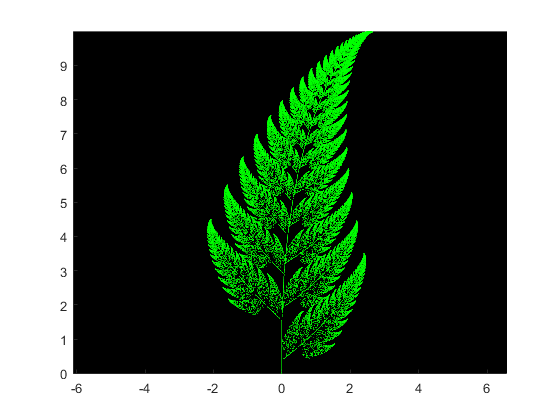

% Create a figure for the animation
figure;
hold on;
axis equal;
set(gca, 'Color', 'k');

% Plot and animate the fern
h = plot(X, Y, '.', 'MarkerSize', 1, 'Color', [0 1 0]);

% Animate the fern to simulate waving in the wind
for t = 1:1000
    % Update the y-coordinates to simulate waving
    Y_wave = Y + wind_strength * sin(wind_speed * t + X);
    set(h, 'YData', Y_wave);
    
    % Pause to create the animation effect
    pause(0.01);
end

hold off;

# Version 2

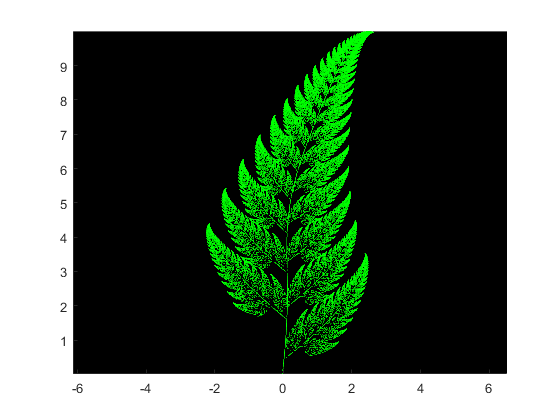

% MATLAB code to create a fractal fern and animate it waving left and right

% Parameters for the fern
iterations = 100000;  % Number of points to plot
scale = 10;  % Scale for plotting
wind_strength = 0.1;  % Strength of the wind effect (left-right movement)
wind_speed = 0.05;  % Speed of the wind effect

% Coefficients for the IFS transformation
p = [0.85, 0.07, 0.07, 0.01];
a = [0.85, 0.20, -0.15, 0];
b = [0.04, -0.26, 0.28, 0];
c = [-0.04, 0.23, 0.26, 0];
d = [0.85, 0.22, 0.24, 0.16];
e = [0, 0, 0, 0];
f = [1.6, 1.6, 0.44, 0];

% Initial point
x = 0;
y = 0;

% Pre-allocate arrays for efficiency
X = zeros(1, iterations);
Y = zeros(1, iterations);

% Generate the fern points using the IFS
for i = 1:iterations
    % Select a transformation with probability p
    r = rand;
    if r < p(1)
        n = 1;
    elseif r < p(1) + p(2)
        n = 2;
    elseif r < p(1) + p(2) + p(3)
        n = 3;
    else
        n = 4;
    end
    
    % Apply the transformation
    new_x = a(n) * x + b(n) * y + e(n);
    new_y = c(n) * x + d(n) * y + f(n);
    
    % Update the point
    x = new_x;
    y = new_y;
    
    % Store the point
    X(i) = x;
    Y(i) = y;
end

% Create a figure for the animation
figure;
hold on;
axis equal;
set(gca, 'Color', 'k');

% Plot and animate the fern
h = plot(X, Y, '.', 'MarkerSize', 1, 'Color', [0 1 0]);

% Animate the fern to simulate waving left and right
for t = 1:1000
    % Update the x-coordinates to simulate waving left and right
    X_wave = X + wind_strength * sin(wind_speed * t + Y);
    set(h, 'XData', X_wave);
    
    % Pause to create the animation effect
    pause(0.01);
end

hold off;

# Version 3

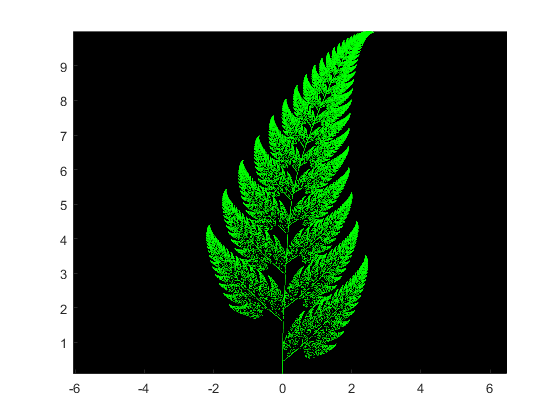

% MATLAB code to create a fractal fern and animate it waving left and right,
% with the root side being static

% Parameters for the fern
iterations = 100000;  % Number of points to plot
scale = 10;  % Scale for plotting
wind_strength = 0.1;  % Strength of the wind effect (left-right movement)
wind_speed = 0.05;  % Speed of the wind effect

% Coefficients for the IFS transformation
p = [0.85, 0.07, 0.07, 0.01];
a = [0.85, 0.20, -0.15, 0];
b = [0.04, -0.26, 0.28, 0];
c = [-0.04, 0.23, 0.26, 0];
d = [0.85, 0.22, 0.24, 0.16];
e = [0, 0, 0, 0];
f = [1.6, 1.6, 0.44, 0];

% Initial point
x = 0;
y = 0;

% Pre-allocate arrays for efficiency
X = zeros(1, iterations);
Y = zeros(1, iterations);

% Generate the fern points using the IFS
for i = 1:iterations
    % Select a transformation with probability p
    r = rand;
    if r < p(1)
        n = 1;
    elseif r < p(1) + p(2)
        n = 2;
    elseif r < p(1) + p(2) + p(3)
        n = 3;
    else
        n = 4;
    end
    
    % Apply the transformation
    new_x = a(n) * x + b(n) * y + e(n);
    new_y = c(n) * x + d(n) * y + f(n);
    
    % Update the point
    x = new_x;
    y = new_y;
    
    % Store the point
    X(i) = x;
    Y(i) = y;
end

% Create a figure for the animation
figure;
hold on;
axis equal;
set(gca, 'Color', 'k');

% Plot and animate the fern
h = plot(X, Y, '.', 'MarkerSize', 1, 'Color', [0 1 0]);

% Normalize the Y data to make the base static
Y_max = max(Y);
Y_min = min(Y);
Y_normalized = (Y - Y_min) / (Y_max - Y_min);

% Animate the fern to simulate waving left and right with a gradient effect
for t = 1:1000
    % Apply the gradient to the waving effect
    X_wave = X + wind_strength * sin(wind_speed * t + Y) .* Y_normalized;
    set(h, 'XData', X_wave);
    
    % Pause to create the animation effect
    pause(0.01);
end

hold off;

**© 07/04/2024, Created by Philip Hotor**